% For computation define as function of 1 vector variable
F.f = @(x) x(1)^2 + 5*x(1)^4 + 10*x(2)^2;
F.df = @(x) [2*x(1) + 20*x(1)^3; 20*x(2)];
F.d2f = @(x) [2 + 60*x(1)^2, 0; 0, 20];

%The parameters of the problem
x0 = [-1; -0.5];
% Initialisation
alpha0 = 1;
tol = 1e-12;
maxIter = 10000;
lsOptsCG_LS.c1 = 1e-4;
lsOptsCG_LS.c2 = 0.1;

stopType = 'grad';

% Initialization
nIter = 0;
normError = 1;
x_k = x0;
df_k = F.df(x_k);
p_k = -df_k;
info.xs = x0;
info.alphas = alpha0;
info.betas = [];
info.coss = [];
stopCond = 0;
alpha_max = alpha0

alpha_max = 1


% Loop until convergence or maximum number of iterations
while (~stopCond && nIter <= maxIter)
    %============================ YOUR CODE HERE =========================================
    if type == 'FR'
        alpha = lineSearch(F, x_k, p_k, alpha_max, lsOptsCG_LS)
        info.alphas(end+1) = alpha
        x_k_1 = x_k
        
        x_k = x_k_1 + alpha*p_k
        info.xs(1,end+1) = x_k(1)
        info.xs(2,end) = x_k(2)
        df_k = F.df(x_k)
        info.coss(end+1) = (-df_k'*p_k)/norm(df_k)*norm(p_k)
        
        beta = (F.df(x_k)'*F.df(x_k))/(F.df(x_k_1)'*F.df(x_k_1))
        %beta = (F.df(x_k)'*(F.df(x_k) - F.df(x_k_1)))/norm(F.df(x_k_1))^2
        info.betas(end+1) = beta
        p_k = -F.df(x_k) + beta*p_k
        
        nIter = nIter+1
    
    if type == 'PR'
        alpha = lineSearch(F, x_k, p_k, alpha_max, lsOptsCG_LS)
        info.alphas(end+1) = alpha
        x_k_1 = x_k
        
        x_k = x_k_1 + alpha*p_k
        info.xs(1,end+1) = x_k(1)
        info.xs(2,end) = x_k(2)
        df_k = F.df(x_k)
        info.coss(end+1) = (-df_k'*p_k)/norm(df_k)*norm(p_k)
        
        beta = (F.df(x_k)'*(F.df(x_k) - F.df(x_k_1)))/norm(F.df(x_k_1))^2
        info.betas(end+1) = beta
        p_k = -F.df(x_k) + beta*p_k
        
        nIter = nIter+1
    end
    
    %=====================================================================================
    
    switch stopType
      case 'step' 
        % Compute relative step length
        normStep = norm(x_k - x_k_1)/norm(x_k_1);
        stopCond = (normStep < tol);
      case 'grad'
        stopCond = (norm(df_k, 'inf') < tol*(1 + abs(F.f(x_k))));
    end
end

alpha = 0.0563

info = struct with fields:
        xs: [2×1 double]
    alphas: [1 0.0563]
     betas: []
      coss: []


x_k_1 =    -1.0000
   -0.5000


x_k =     0.2375
    0.0625


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 0.0563]
     betas: []
      coss: []


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 0.0563]
     betas: []
      coss: []


df_k =     0.7429
    1.2500


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 0.0563]
     betas: []
      coss: -479.3697


beta = 0.0530

info = struct with fields:
        xs: [2×2 double]
    alphas: [1 0.0563]
     betas: 0.0530
      coss: -479.3697


p_k =     0.4233
   -0.7199


nIter = 1

alpha = 0.0563

info = struct with fields:
        xs: [2×2 double]
    alphas: [1 0.0563 0.0563]
     betas: 0.0530
      coss: -479.3697


x_k_1 =     0.2375
    0.0625


x_k =     0.2613
    0.0220


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 0.0563 0.0563]
     betas: 0.0530
      coss: -479.3697


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 0.0563 0.0563]
     betas: 0.0530
      coss: -479.3697


df_k =     0.8795
    0.4401


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 0.0563 0.0563]
     betas: 0.0530
      coss: [-479.3697 -0.0471]


beta = -0.1118

info = struct with fields:
        xs: [2×3 double]
    alphas: [1 0.0563 0.0563]
     betas: [0.0530 -0.1118]
      coss: [-479.3697 -0.0471]


p_k =    -0.9268
   -0.3597


nIter = 2

alpha = 0.1688

info = struct with fields:
        xs: [2×3 double]
    alphas: [1 0.0563 0.0563 0.1688]
     betas: [0.0530 -0.1118]
      coss: [-479.3697 -0.0471]


x_k_1 =     0.2613
    0.0220


x_k =     0.1049
   -0.0387


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 0.0563 0.0563 0.1688]
     betas: [0.0530 -0.1118]
      coss: [-479.3697 -0.0471]


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 0.0563 0.0563 0.1688]
     betas: [0.0530 -0.1118]
      coss: [-479.3697 -0.0471]


df_k =     0.2329
   -0.7737


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 0.0563 0.0563 0.1688]
     betas: [0.0530 -0.1118]
      coss: [-479.3697 -0.0471 -0.0768]


beta = 0.8154

info = struct with fields:
        xs: [2×4 double]
    alphas: [1 0.0563 0.0563 0.1688]
     betas: [0.0530 -0.1118 0.8154]
      coss: [-479.3697 -0.0471 -0.0768]


p_k =    -0.9886
    0.4805


nIter = 3

alpha = 0.0844

info = struct with fields:
        xs: [2×4 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844]
     betas: [0.0530 -0.1118 0.8154]
      coss: [-479.3697 -0.0471 -0.0768]


x_k_1 =     0.1049
   -0.0387


x_k =     0.0215
    0.0019


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844]
     betas: [0.0530 -0.1118 0.8154]
      coss: [-479.3697 -0.0471 -0.0768]


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844]
     betas: [0.0530 -0.1118 0.8154]
      coss: [-479.3697 -0.0471 -0.0768]


df_k =     0.0432
    0.0371


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844]
     betas: [0.0530 -0.1118 0.8154]
      coss: [-479.3697 -0.0471 -0.0768 0.4806]


beta = 0.0335

info = struct with fields:
        xs: [2×5 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335]
      coss: [-479.3697 -0.0471 -0.0768 0.4806]


p_k =    -0.0763
   -0.0210


nIter = 4

alpha = 0.1969

info = struct with fields:
        xs: [2×5 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969]
     betas: [0.0530 -0.1118 0.8154 0.0335]
      coss: [-479.3697 -0.0471 -0.0768 0.4806]


x_k_1 =     0.0215
    0.0019


x_k =     0.0065
   -0.0023


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969]
     betas: [0.0530 -0.1118 0.8154 0.0335]
      coss: [-479.3697 -0.0471 -0.0768 0.4806]


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969]
     betas: [0.0530 -0.1118 0.8154 0.0335]
      coss: [-479.3697 -0.0471 -0.0768 0.4806]


df_k =     0.0130
   -0.0456


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969]
     betas: [0.0530 -0.1118 0.8154 0.0335]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05]


beta = 1.0405

info = struct with fields:
        xs: [2×6 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05]


p_k =    -0.0924
    0.0237


nIter = 5

alpha = 0.0844

info = struct with fields:
        xs: [2×6 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05]


x_k_1 =     0.0065
   -0.0023


x_k =    -0.0013
   -0.0003


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05]


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05]


df_k =    -0.0026
   -0.0055


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017]


beta = -0.0804

info = struct with fields:
        xs: [2×7 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017]


p_k =     0.0101
    0.0036


nIter = 6

alpha = 0.0984

info = struct with fields:
        xs: [2×7 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017]


x_k_1 =    -0.0013
   -0.0003


x_k = 	1.0e+-3 *

   -0.3264
    0.0802


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017]


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017]


df_k =    -0.0007
    0.0016


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06]


beta = 0.2707

info = struct with fields:
        xs: [2×8 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06]


p_k =     0.0034
   -0.0006


nIter = 7

alpha = 0.1125

info = struct with fields:
        xs: [2×8 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06]


x_k_1 = 	1.0e+-3 *

   -0.3264
    0.0802


x_k = 	1.0e+-4 *

    0.5333
    0.1008


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06]


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06]


df_k = 	1.0e+-3 *

    0.1067
    0.2017


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06]


beta = -0.0673

info = struct with fields:
        xs: [2×9 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06]


p_k = 	1.0e+-3 *

   -0.3338
   -0.1597


nIter = 8

alpha = 0.0844

info = struct with fields:
        xs: [2×9 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06]


x_k_1 = 	1.0e+-4 *

    0.5333
    0.1008


x_k = 	1.0e+-4 *

    0.2517
   -0.0339


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06]


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06]


df_k = 	1.0e+-4 *

    0.5034
   -0.6784


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08]


beta = 0.2968

info = struct with fields:
        xs: [2×10 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08]


p_k = 	1.0e+-3 *

   -0.1494
    0.0204


nIter = 9

alpha = 0.1688

info = struct with fields:
        xs: [2×10 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08]


x_k_1 = 	1.0e+-4 *

    0.2517
   -0.0339


x_k = 	1.0e+-7 *

   -0.4491
    0.5629


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08]


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08]


df_k = 	1.0e+-5 *

   -0.0090
    0.1126


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09]


beta = 0.0115

info = struct with fields:
        xs: [2×11 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09]


p_k = 	1.0e+-5 *

   -0.1631
   -0.0891


nIter = 10

alpha = 0.0422

info = struct with fields:
        xs: [2×11 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09]


x_k_1 = 	1.0e+-7 *

   -0.4491
    0.5629


x_k = 	1.0e+-6 *

   -0.1137
    0.0187


info = struct with fields:
        xs: [2×12 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09]


info = struct with fields:
        xs: [2×12 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09]


df_k = 	1.0e+-6 *

   -0.2274
    0.3745


info = struct with fields:
        xs: [2×12 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13]


beta = -0.1960

info = struct with fields:
        xs: [2×12 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13]


p_k = 	1.0e+-6 *

    0.5471
   -0.1999


nIter = 11

alpha = 0.1406

info = struct with fields:
        xs: [2×12 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13]


x_k_1 = 	1.0e+-6 *

   -0.1137
    0.0187


x_k = 	1.0e+-7 *

   -0.3677
   -0.0938


info = struct with fields:
        xs: [2×13 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13]


info = struct with fields:
        xs: [2×13 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13]


df_k = 	1.0e+-6 *

   -0.0735
   -0.1877


info = struct with fields:
        xs: [2×13 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15]


beta = 0.4908

info = struct with fields:
        xs: [2×13 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15]


p_k = 	1.0e+-6 *

    0.3420
    0.0896


nIter = 12

alpha = 0.1125

info = struct with fields:
        xs: [2×13 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15]


x_k_1 = 	1.0e+-7 *

   -0.3677
   -0.0938


x_k = 	1.0e+-8 *

    0.1709
    0.0695


info = struct with fields:
        xs: [2×14 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15]


info = struct with fields:
        xs: [2×14 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15]


df_k = 2×1
    0.0342
    0.1391


info = struct with fields:
        xs: [2×14 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14]


beta = 0.0755

info = struct with fields:
        xs: [2×14 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14]


p_k = 2×1
    0.2240
   -0.0715


nIter = 13

alpha = 0.0105

info = struct with fields:
        xs: [2×14 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14]


x_k_1 = 2×1
    0.1709
    0.0695


x_k = 2×1
    0.1945
    0.0620


info = struct with fields:
        xs: [2×15 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14]


info = struct with fields:
        xs: [2×15 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14]


df_k = 2×1
    0.0389
    0.1240


info = struct with fields:
        xs: [2×15 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18]


beta = -0.0822

info = struct with fields:
        xs: [2×15 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18]


p_k = 2×1
   -0.0573
   -0.1181


nIter = 14

alpha = 0.0563

info = struct with fields:
        xs: [2×15 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18]


x_k_1 = 2×1
    0.1945
    0.0620


x_k = 2×1
    0.1623
   -0.0044


info = struct with fields:
        xs: [2×16 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18]


info = struct with fields:
        xs: [2×16 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18]


df_k = 2×1
    0.3246
   -0.0890


info = struct with fields:
        xs: [2×16 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17]


beta = 0.0576

info = struct with fields:
        xs: [2×16 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17]


p_k = 2×1
   -0.3576
    0.0209


nIter = 15

alpha = 0.4500

info = struct with fields:
        xs: [2×16 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17]


x_k_1 = 2×1
    0.1623
   -0.0044


x_k = 2×1
    0.1373
    0.4959


info = struct with fields:
        xs: [2×17 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17]


info = struct with fields:
        xs: [2×17 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17]


df_k = 2×1
    0.0275
    0.9919


info = struct with fields:
        xs: [2×17 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19]


beta = 0.1570

info = struct with fields:
        xs: [2×17 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19]


p_k = 2×1
   -0.5887
   -0.9591


nIter = 16

alpha = 0.0492

info = struct with fields:
        xs: [2×17 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19]


x_k_1 = 2×1
    0.1373
    0.4959


x_k = 2×1
   -0.1524
    0.0239


info = struct with fields:
        xs: [2×18 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19]


info = struct with fields:
        xs: [2×18 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19]


df_k = 2×1
   -0.3049
    0.4780


info = struct with fields:
        xs: [2×18 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19]


beta = -0.0440

info = struct with fields:
        xs: [2×18 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19]


p_k = 2×1
    0.5641
   -0.0556


nIter = 17

alpha = 0.2813

info = struct with fields:
        xs: [2×18 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19]


x_k_1 = 2×1
   -0.1524
    0.0239


x_k = 2×1
    0.6229
    0.8253


info = struct with fields:
        xs: [2×19 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19]


info = struct with fields:
        xs: [2×19 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19]


df_k = 2×1
    0.0125
    0.1651


info = struct with fields:
        xs: [2×19 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23]


beta = -0.1484

info = struct with fields:
        xs: [2×19 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23]


p_k = 2×1
   -0.0962
   -0.1568


nIter = 18

alpha = 0.0563

info = struct with fields:
        xs: [2×19 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23]


x_k_1 = 2×1
    0.6229
    0.8253


x_k = 2×1
    0.8190
   -0.5672


info = struct with fields:
        xs: [2×20 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23]


info = struct with fields:
        xs: [2×20 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23]


df_k = 2×1
    0.0164
   -0.1134


info = struct with fields:
        xs: [2×20 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22]


beta = 0.0724

info = struct with fields:
        xs: [2×20 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22]


p_k = 2×1
   -0.8600
   -0.0007


nIter = 19

alpha = 0.0984

info = struct with fields:
        xs: [2×20 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22]


x_k_1 = 2×1
    0.8190
   -0.5672


x_k = 2×1
   -0.0275
   -0.5678


info = struct with fields:
        xs: [2×21 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22]


info = struct with fields:
        xs: [2×21 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22]


df_k = 2×1
   -0.0006
   -0.1136


info = struct with fields:
        xs: [2×21 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27]


beta = 0.0018

info = struct with fields:
        xs: [2×21 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27]


p_k = 2×1
    0.0004
    0.1136


nIter = 20

alpha = 0.0492

info = struct with fields:
        xs: [2×21 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27]


x_k_1 = 2×1
   -0.0275
   -0.5678


x_k = 2×1
   -0.2561
   -0.0887


info = struct with fields:
        xs: [2×22 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27]


info = struct with fields:
        xs: [2×22 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27]


df_k = 2×1
   -0.0512
   -0.1775


info = struct with fields:
        xs: [2×22 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27 1.2405e-24]


beta = -0.0154

info = struct with fields:
        xs: [2×22 double]
    alphas: [1 0.0563 0.0563 0.1688 0.0844 0.1969 0.0844 0.0984 0.1125 0.0844 0.1688 0.0422 0.1406 0.1125 0.0105 0.0563 0.4500 0.0492 0.2812 0.0563 0.0984 0.0492]
     betas: [0.0530 -0.1118 0.8154 0.0335 1.0405 -0.0804 0.2707 -0.0673 0.2968 0.0115 -0.1960 0.4908 0.0755 -0.0822 0.0576 0.1570 -0.0440 -0.1484 0.0724 0.0018 -0.0154]
      coss: [-479.3697 -0.0471 -0.0768 0.4806 5.4940e-05 -0.0017 4.6245e-06 -3.5240e-06 2.6130e-08 -4.8638e-09 -1.5848e-13 7.8560e-15 -5.9624e-14 2.6856e-18 3.1569e-17 -3.9399e-19 5.5368e-19 7.3785e-23 -2.6018e-22 -4.1540e-27 1.2405e-24]


p_k = 2×1
    0.5061
    0.0276


nIter = 21


% Assign output values 
xMin = x_k;
fMin = F.f(x_k); 

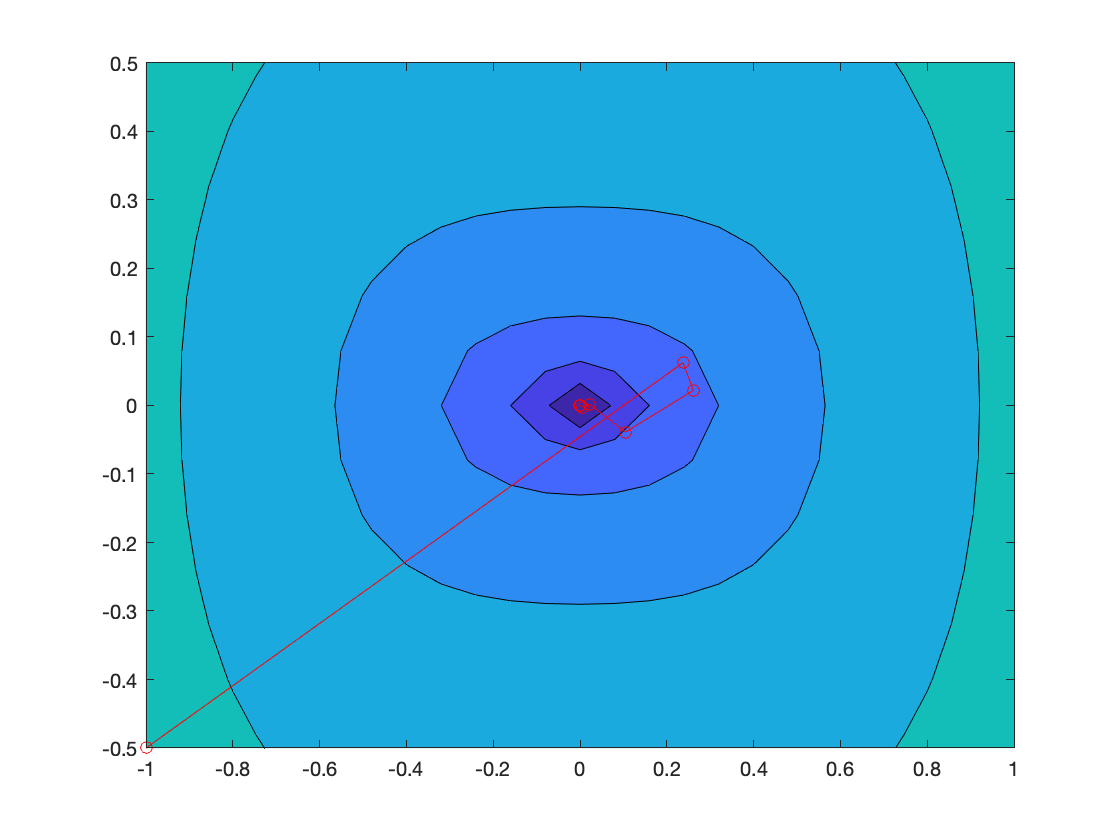

%Plotting the iterates
f1 = @(x,y) x.^2 + 5*x.^4 + 10.*y.^2;
n = 300;
x = linspace(-12,12,n+1);
y = x;
[X,Y] = meshgrid(x,y);
Z = log(max(f1(X,Y), 1e-3));

figure, contourf(X, Y, Z,10); hold on
%figure, surf(beta*X, beta*Y, log(f1(beta*X, beta*Y)), 'EdgeColor', 'none'); hold on
%[XS, YS] = meshgrid(info.xs(1,:), info.xs(2,:))
plot(info.xs(1,:), info.xs(2,:), 'or-')
xlim([-1 1])
ylim([-0.5 0.5])

%title('Steepest descent method with backtracking line search, x_0 = [1.2;1.2]')
%saveas(gcf,'7CFRa3.png')

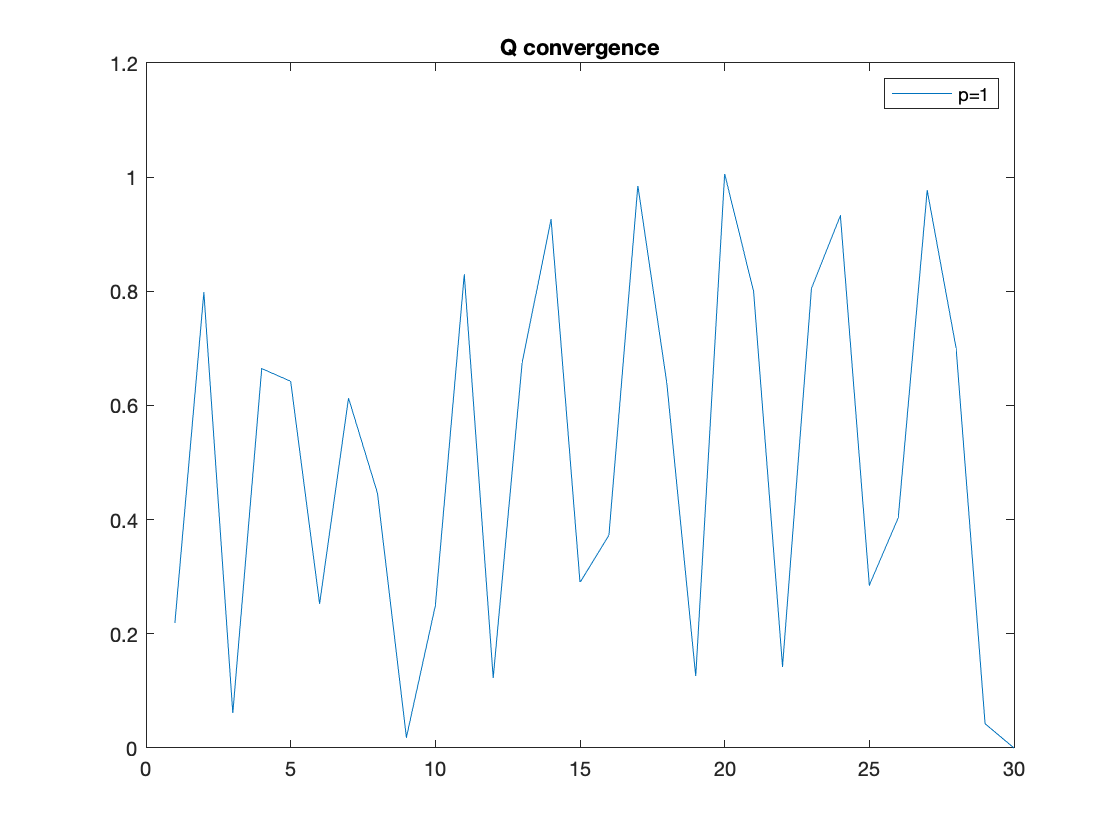

%Investigating convergence
conSteep = convergenceHistory(info, info.xs(:,end), F, 2); % using 2-norm

p = 1; 
% convergance rate
rs1 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
ps=1.4; rss = conSteep.x(2:end)./(conSteep.x(1:end-1).^ps); 
p=2; rs2 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
figure, plot(rs1); hold on; title('Q convergence'); legend('p=1')

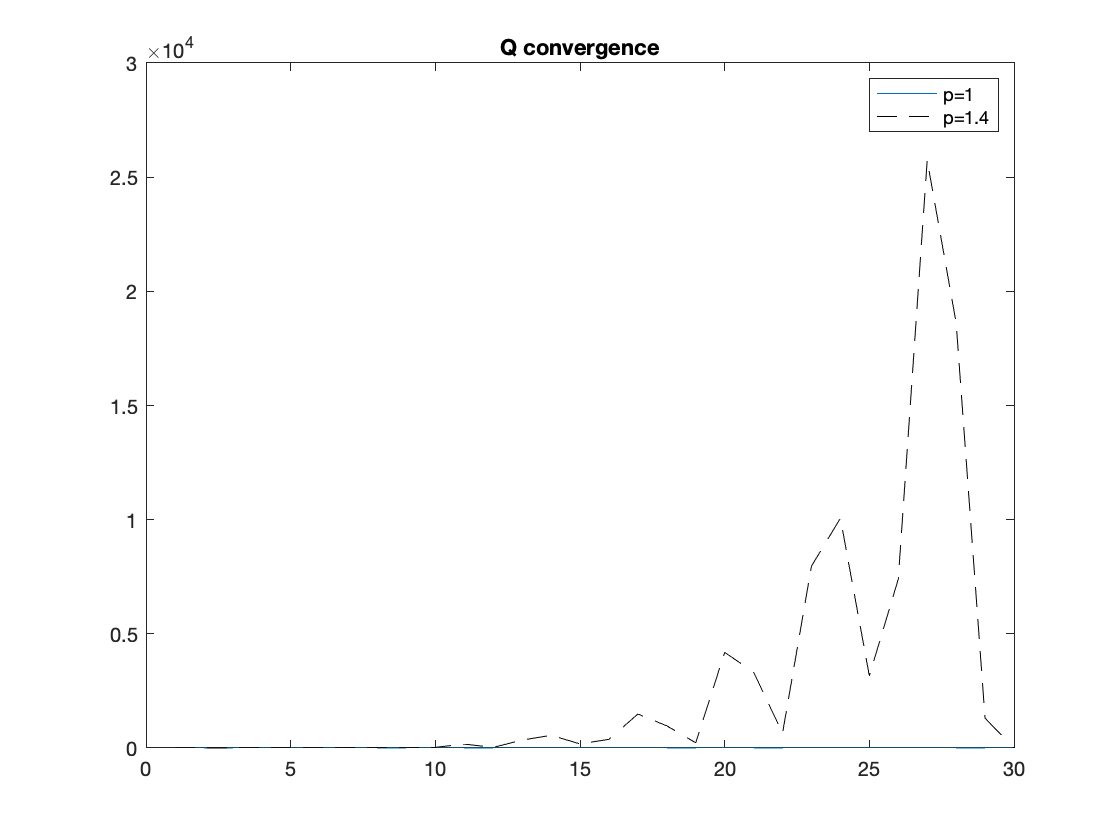

%saveas(gcf, 'FR2_Q1.png')
figure, plot(rs1); hold on; plot(rss,'k--'); title('Q convergence'); legend('p=1',['p=' num2str(ps)])

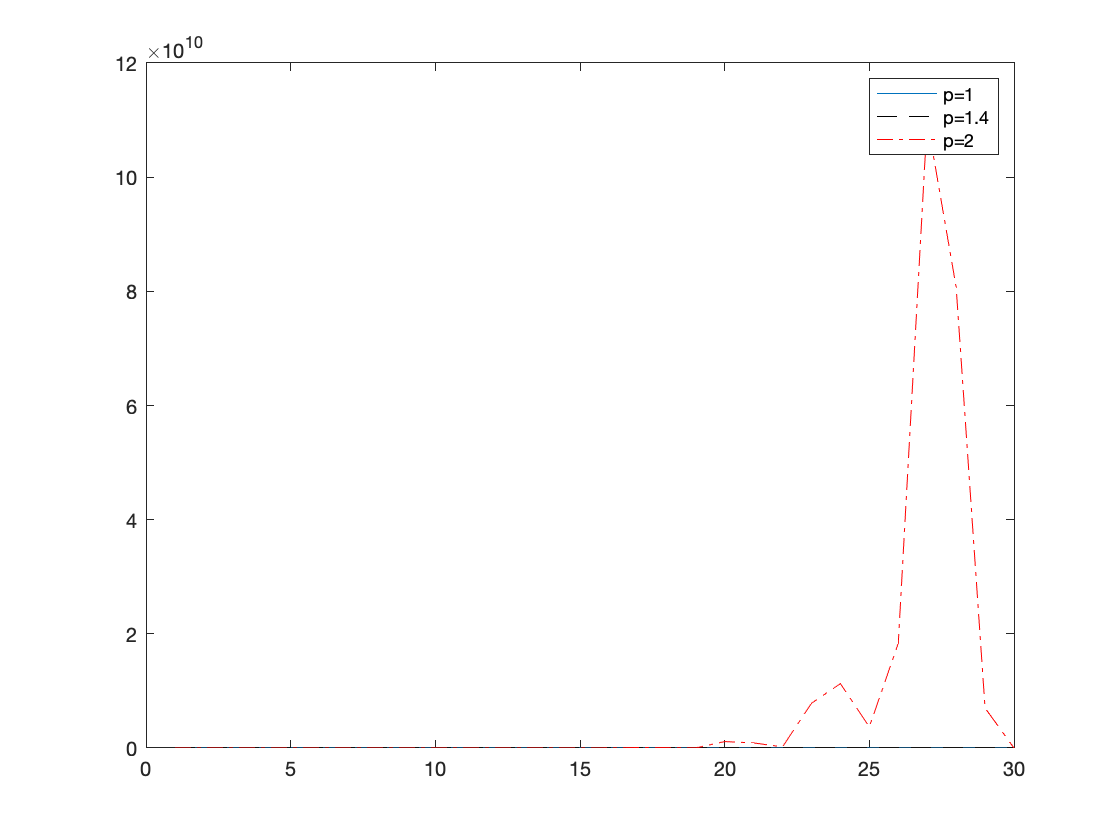

%saveas(gcf, 'un_conv_2', 'epsc')
figure, plot(rs1); hold on; plot(rss,'k--'); plot(rs2,'r-.'); legend('p=1',['p=' num2str(ps)],'p=2')

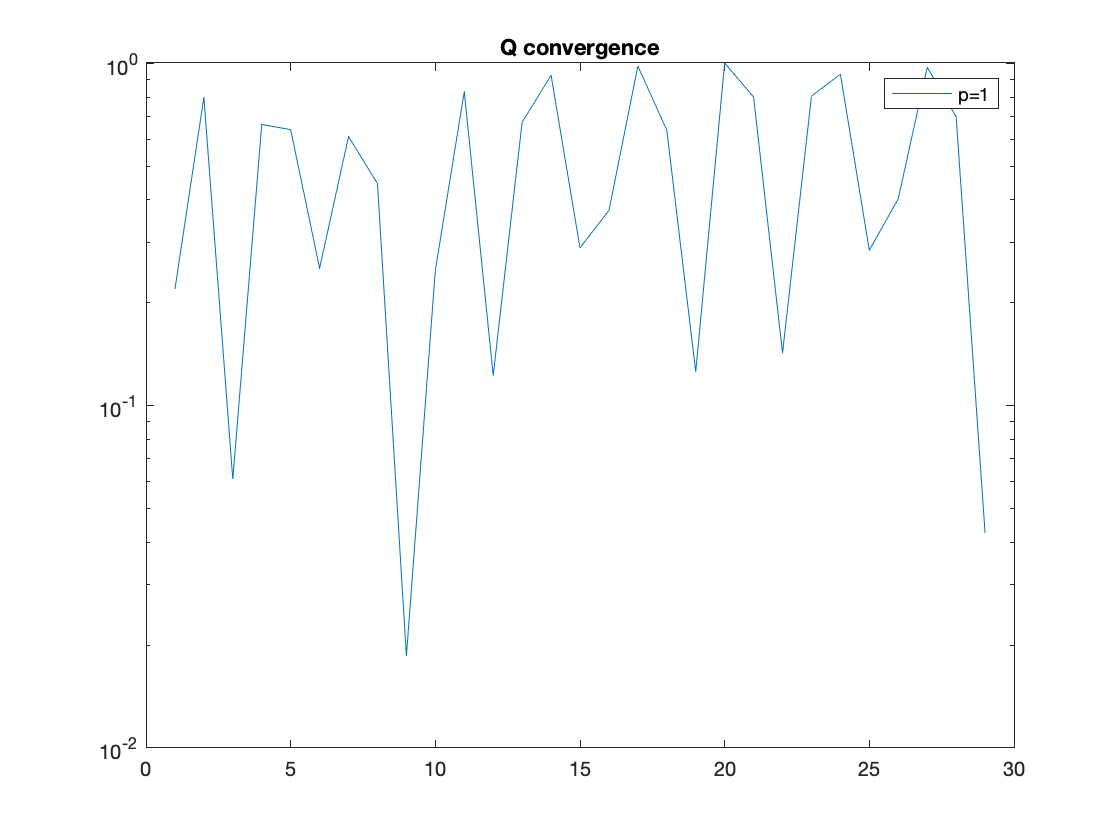

%saveas(gcf, 'FR2_Q2.png')
figure, semilogy(rs1); hold on; title('Q convergence'); legend('p=1')